# Stribeck Curve Fitting from Data

## Import Data

Model_Parameters;
load("torque_curve_calculation.mat");


## Data Preparation

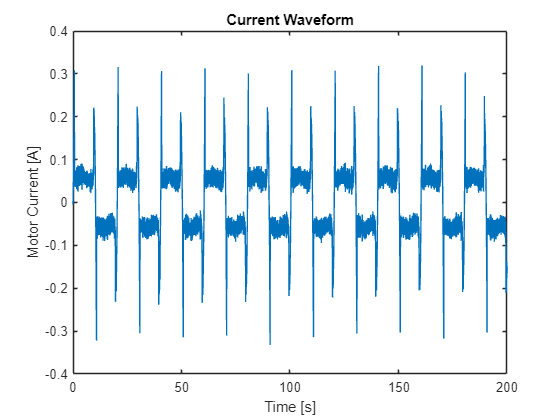

% Data Vector
current_vec = out.torque_curve_sim.signals(1).values;   % Current
speed_vec = out.torque_curve_sim.signals(2).values;     % Speed
time = out.torque_curve_sim.time;                                        % Time

plot(time, current_vec)
title('Current Waveform')
xlabel('Time [s]')
ylabel('Motor Current [A]')

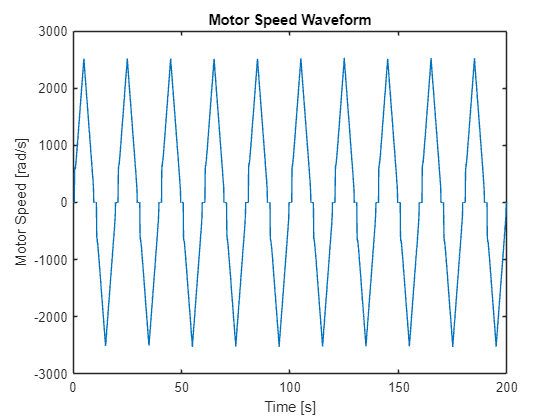

plot(time, speed_vec)
title('Motor Speed Waveform')
xlabel('Time [s]')
ylabel('Motor Speed [rad/s]')

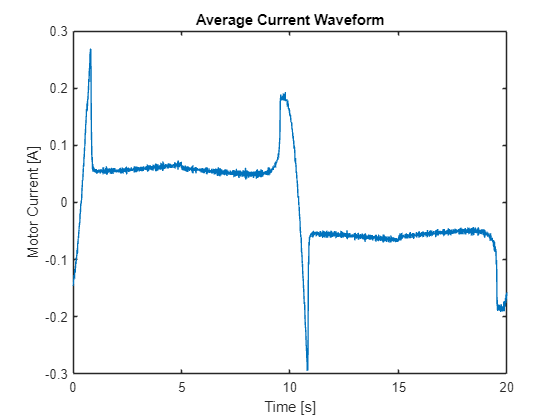

% Reshape and Mean
mean_current_vec = mean(reshape(current_vec(1:end-1), 20000, []), 2);
mean_speed_vec = mean(reshape(speed_vec(1:end-1), 20000, []), 2);

plot(time(1:20000), mean_current_vec)
title('Average Motor Current Waveform')
xlabel('Time [s]')
ylabel('Motor Current [A]')

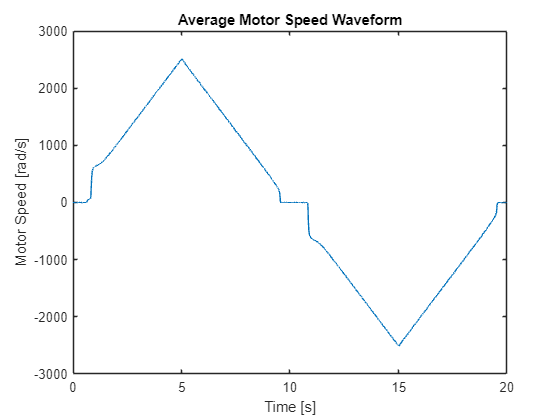


plot(time(1:20000), mean_speed_vec)
title('Average Motor Speed Waveform')
xlabel('Time [s]')
ylabel('Motor Speed [rad/s]')

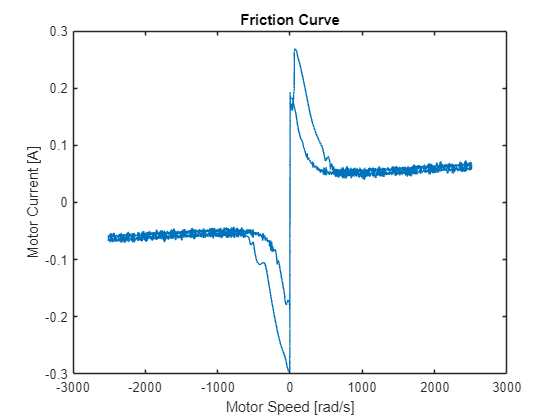

plot(mean_speed_vec, mean_current_vec)
title('Friction Curve')
xlabel('Motor Speed [rad/s]')
ylabel('Motor Current [A]')

## Data Fitting Code

% Compare the fitted curve equation with the data on the same graph
% treat positive and negative quadrant as 2 different fittings
% treat hysteresis as 2 different fitting